# **Plot Symbolic Functions**

Symbolic Math Toolbox provides the plotting functions:

- [`fplot`](https://www.mathworks.com/help/releases/R2023b/symbolic/fplot.html) to create 2-D plots of symbolic expressions, equations, or functions in Cartesian coordinates.

- [`fplot3`](https://www.mathworks.com/help/releases/R2023b/symbolic/fplot3.html) to create 3-D parametric plots.

- [`ezpolar`](https://www.mathworks.com/help/releases/R2023b/symbolic/ezpolar.html) to create plots in polar coordinates.

- [`fsurf`](https://www.mathworks.com/help/releases/R2023b/symbolic/fsurf.html) to create surface plots.

- [`fcontour`](https://www.mathworks.com/help/releases/R2023b/symbolic/fcontour.html) to create contour plots.

- [`fmesh`](https://www.mathworks.com/help/releases/R2023b/symbolic/fmesh.html) to create mesh plots.

## **Explicit Function Plot**

Create a 2-D line plot by using `fplot`. Plot the expression *x*3−6*x*2+11*x*−6.

syms x
f = x^3 - 6*x^2 + 11*x - 6;
fplot(f,'Linewidth',2)

Add labels for the x- and y-axes. Generate the title by using texlabel(f). Show the grid by using grid on. For details, see Add Title and Axis Labels to Chart.

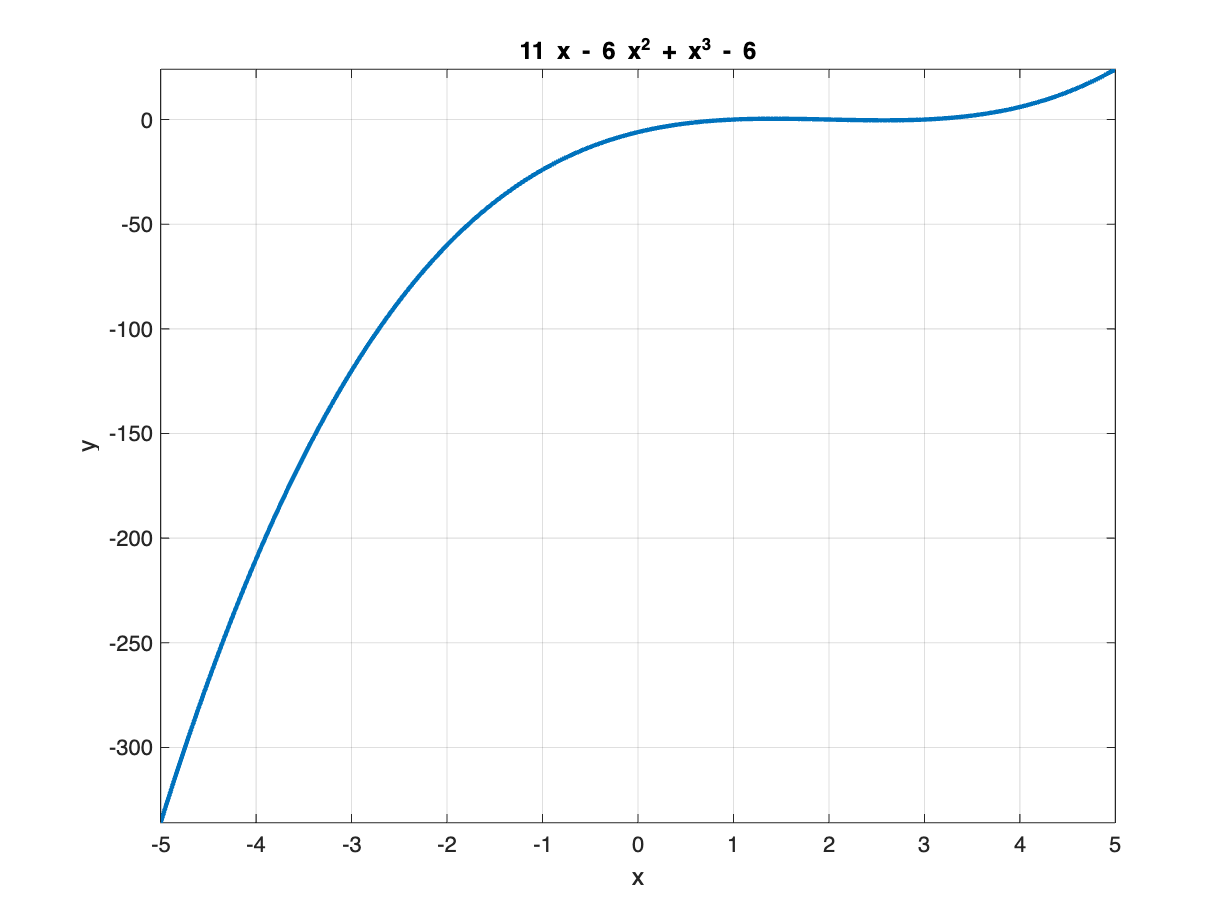


xlabel('x')
ylabel('y')
title(texlabel(f))
grid on

## Implicit Function Plot

Plot equations and implicit functions using `fimplicit`.

Plot the equation $(x^2 + y^2)^4 = (x^2 - y^2)^2$ over $-1 < x < 1$.

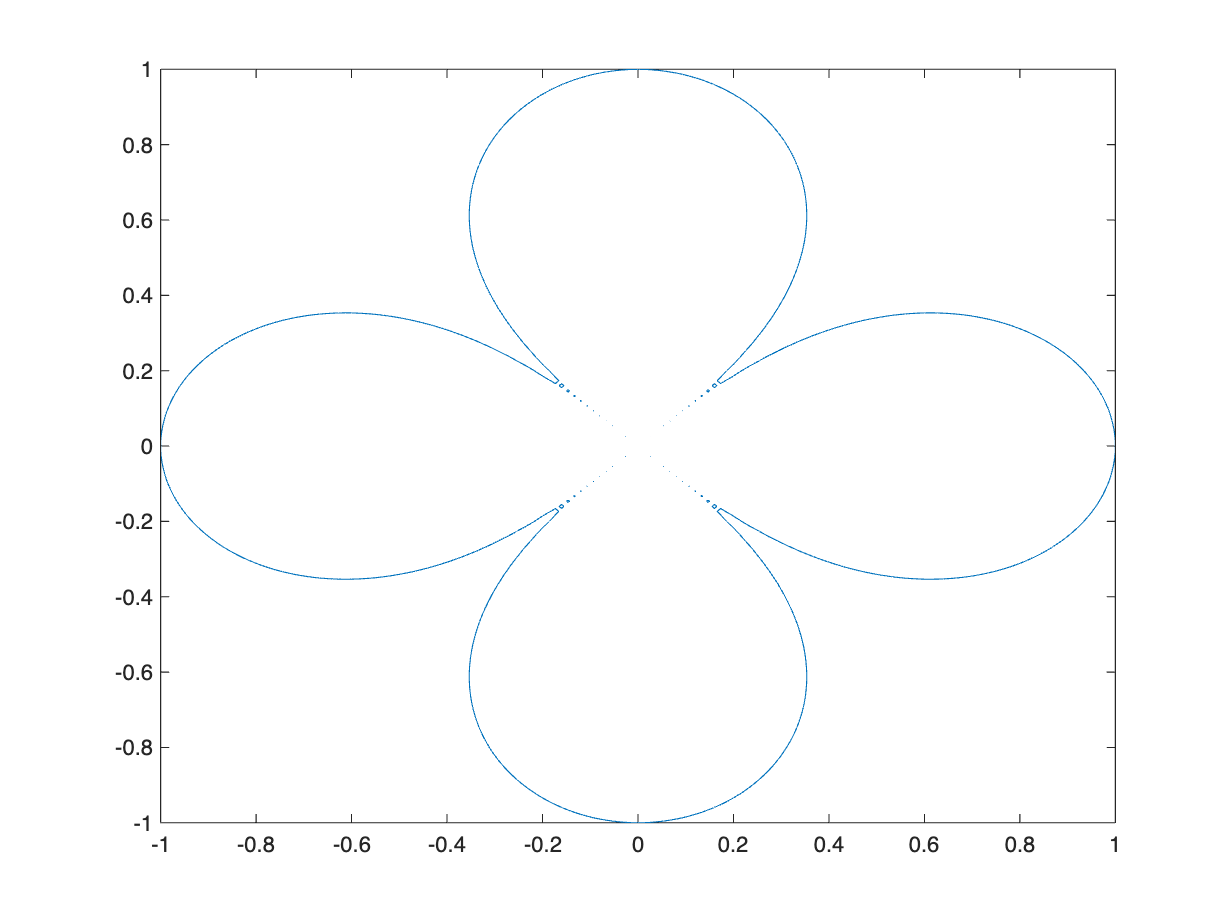

syms x y
eqn = (x^2 + y^2)^4 == (x^2 - y^2)^2;
fimplicit(eqn, [-1 1])

## 3-D Plot

Plot 3-D parametric lines by using fplot3.

Plot the parametric line

x=t^2*sin(10*t)

y=t^2*cos(10*t)

z=t

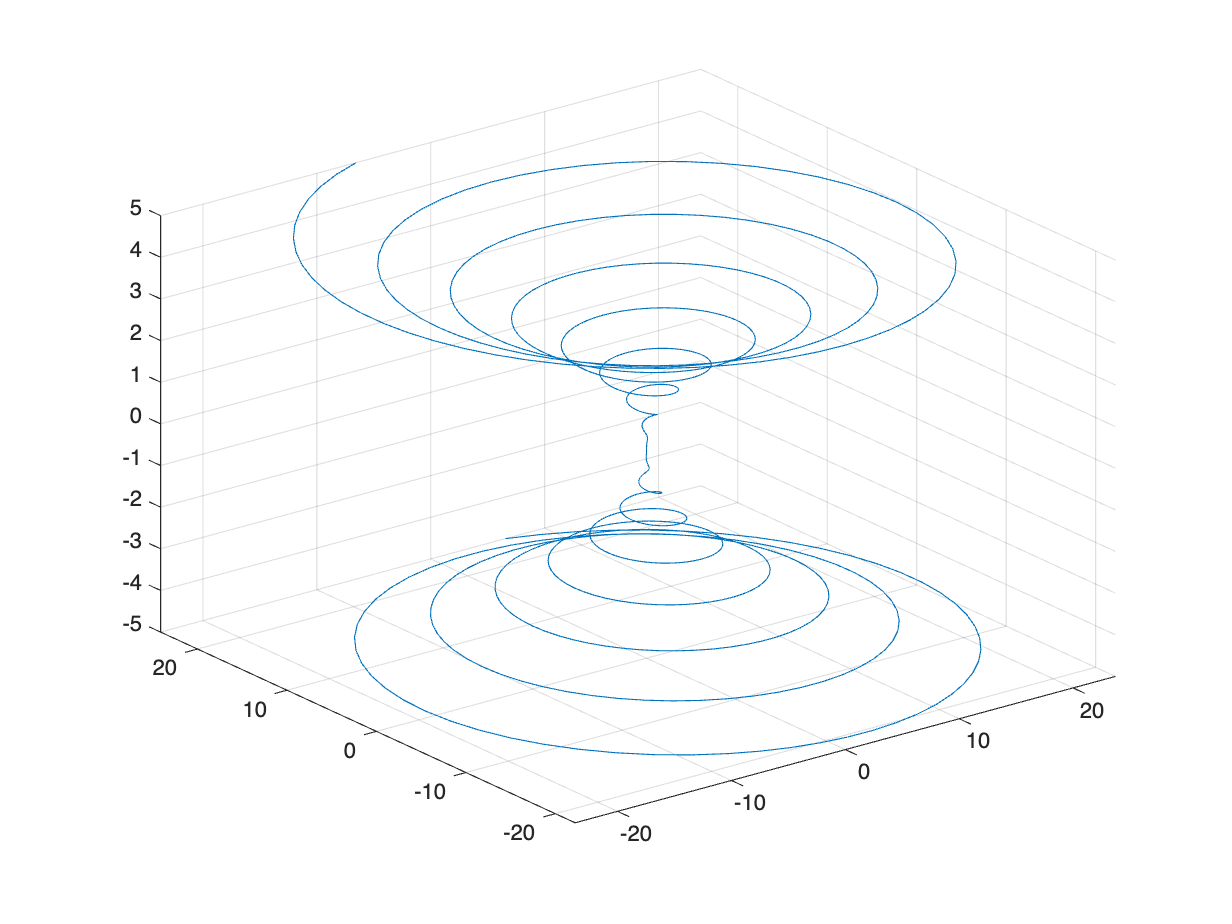

syms t
fplot3(t^2*sin(10*t), t^2*cos(10*t), t)

## Create Surface Plot

Create a 3-D surface by using fsurf.

Plot the paraboloid 

z=x^2+y^2

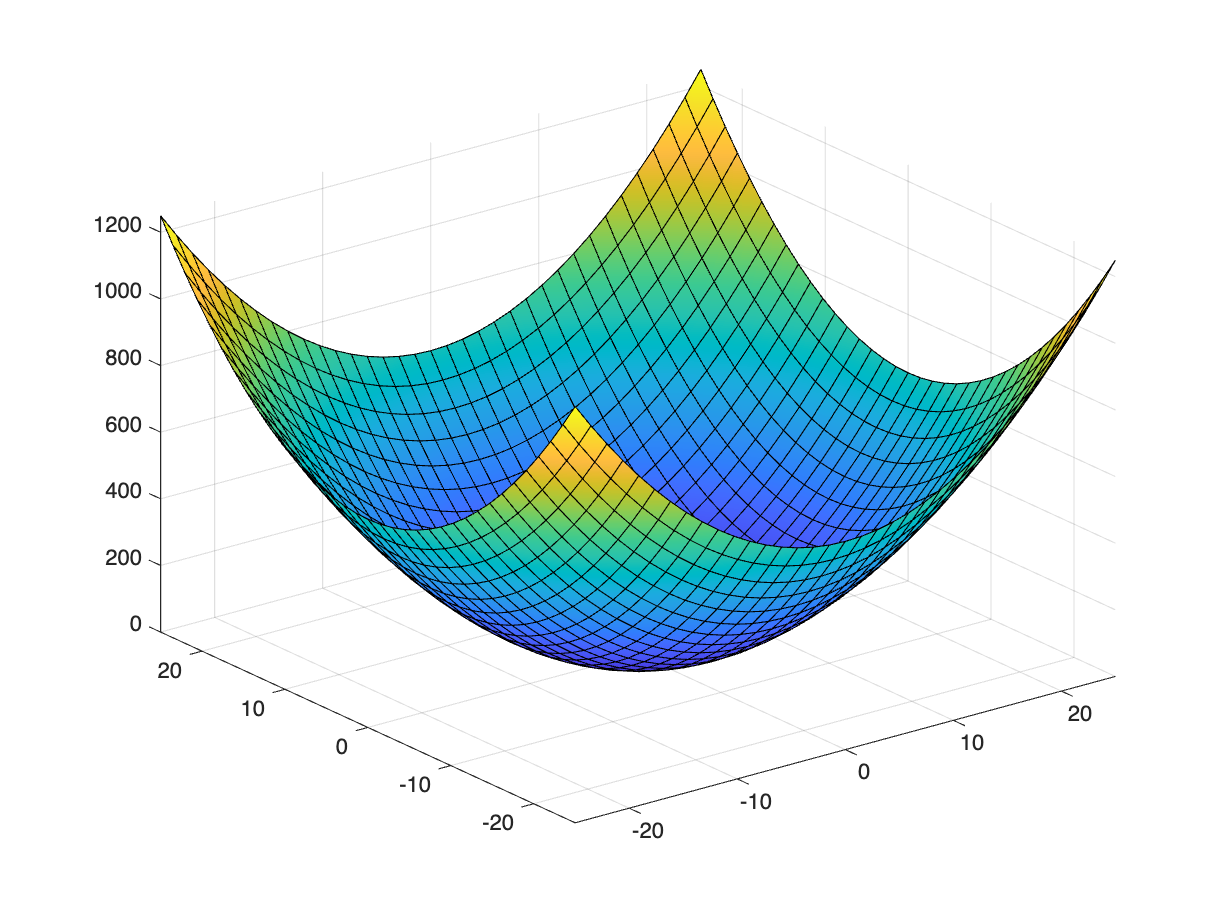

syms x y
fsurf(x^2 + y^2)